clc;clear;

I = im2double(im2gray(imread("Train/captcha_0444.png")));

fourier = fftshift(fft2(I));
fourier2 = fftshift(fft2(I));
%imagesc(log(abs(fourier)))
absFourier = abs(fourier);
maxValue = max(absFourier(:));
thresh_val = 0.01 * maxValue;
mask = absFourier < thresh_val;
fourierFilt = fourier .* mask;
fourier(160,211) = 0;
fourier(157,204) = 0;
fourier(166,225) = 0;
fourier(169,232) = 0;
filteredImage = ifft2(ifftshift(fourier)) + mean2(I);
filteredImage = mat2gray(real(filteredImage));
% crop = filteredImage(1:100, 1:100); imshow(crop); cropHist = imhist(crop);
% J = imgaussfilt(filteredImage,4);
% imshow(J);
X1 = EM_DenoiseTV(filteredImage,0.2);
X2 =  histeq(X1);
absJ = abs(X1);
maxValueJ = max(absJ(:));
binaryImage = X2 < 0.09;
original = binaryImage

disk = strel("disk",1);
% for i = 1:2
%     binaryImage = imerode(binaryImage,SE);
% end
binaryImage = original;
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imdilate(binaryImage,disk);
binaryImage = imdilate(binaryImage,disk);
%Crop
stats = regionprops(binaryImage, 'BoundingBox');
allBoundingBoxes = cat(1, stats.BoundingBox);
xMin = min(allBoundingBoxes(:, 1))
yMin = min(allBoundingBoxes(:, 2))
xMax = 0
yMax =0
[nBoxes,~] = size(allBoundingBoxes)
for q=1:nBoxes
    if allBoundingBoxes(q,1)+allBoundingBoxes(q,3) > xMax
        xMax=allBoundingBoxes(q,1)+allBoundingBoxes(q,3)
    end
    if allBoundingBoxes(q,2)+allBoundingBoxes(q,4) > yMax
        yMax=allBoundingBoxes(q,2)+allBoundingBoxes(q,4)
    end
end
% Get the minimum bounding box that encloses all objects
enclosingBox = [xMin,yMin,xMax-xMin,yMax-yMin];
% Crop the binary image using the enclosing bounding box
croppedImage = imcrop(binaryImage, enclosingBox);

%Split Image
sections = split_correlation_map(croppedImage,3);
max_digit = cell(1,3);

%Load templates 
imagefiles = dir('Templates/*.jpg');      
nfiles = length(imagefiles);    % Number of files found

images = cell(1,nfiles);
for ii=1:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(currentfilename);
   images{1,ii} = currentimage;
end 

for i=1:3
    area = sections(:,:,i)
    stats = regionprops(area, 'BoundingBox');
    allBoundingBoxes = cat(1, stats.BoundingBox);
    xMin = min(allBoundingBoxes(:, 1))
    yMin = min(allBoundingBoxes(:, 2))
    xMax = 0
    yMax =0
    [nBoxes,~] = size(allBoundingBoxes)
    for q=1:nBoxes
        if allBoundingBoxes(q,1)+allBoundingBoxes(q,3) > xMax
            xMax=allBoundingBoxes(q,1)+allBoundingBoxes(q,3)
        end
        if allBoundingBoxes(q,2)+allBoundingBoxes(q,4) > yMax
            yMax=allBoundingBoxes(q,2)+allBoundingBoxes(q,4)
        end
    end
    % Get the minimum bounding box that encloses all objects
    enclosingBox = [xMin,yMin,xMax-xMin,yMax-yMin];
    % Crop the binary image using the enclosing bounding box
    croppedImage = imcrop(area, enclosingBox);
    background = croppedImage*255;
    current_max=0
    max_value=0
    for l = 1:nfiles
        correlation_map = templatematch(background,images{1,l});
        current_max = max(correlation_map,[],'all');
        if(current_max > max_values)
            max_value=current_max;
            max_digit{1,i} = images{1,l};
        end
    end
end
% Find the bounding box that encapsulates all objects

figure;
subplot(1, 2, 1);
imshow(filteredImage);
title('original');

subplot(1, 2, 2);
imshow(croppedImage);
title('filtered');

%Rotate it
% test2 = imrotate(test2,-30)
%Call cross correlation matching in fourier domain
% out =templatematch(binaryImage*255,test2);
% %Draw the template
% template  = test2;

% %crop background
% bx = size(background, 2); 
% by = size(background, 1);
% tx = size(template, 2);
% ty = size(template, 1);

%% display best match
% hFig = figure;
% hAx  = axes;
% position = [x, y, tx, ty];
% imshow(background);
% drawrectangle('Position',position);
% templates=[test2]
% rotations=[0,10,20,30,-10,-20,-30]
%for template in templates:
%    for rotation in rotation:



max_values = zeros(1,3);





% Iterate over 3,4,5 for different scales and rotations
    % Compute top 3 region of matches (To catch 333,444,555 etc)
% Take top 3 matches out of all matches and thats the prediction

I = im2double(im2gray(im));
    %Filter structured noise in fourier domain
    fourier = fftshift(fft2(I));
    fourier(160,211) = 0;
    fourier(157,204) = 0;
    fourier(166,225) = 0;
    fourier(169,232) = 0;
    filteredImage = ifft2(ifftshift(fourier)) + mean2(I);
    filteredImage = mat2gray(real(filteredImage));
    %Remove gaussian noise using energy minimisation
    eMin = EM_DenoiseTV(filteredImage,0.2, @(varargin) disp(''),1000);
    eMinEq =  histeq(eMin);
    %Threshold for digits
    noisyDigits = eMinEq < 0.09;
    %Remove lines using morphology
    disk = strel("disk",1);
    binaryImage = imerode(noisyDigits,disk);
    binaryImage = imerode(binaryImage,disk);
    binaryImage = imerode(binaryImage,disk);
    binaryImage = imerode(binaryImage,disk);
    binaryImage = imerode(binaryImage,disk);
    binaryImage = imdilate(binaryImage,disk);
    binaryImage = imdilate(binaryImage,disk);
    %Crop to just digits
    croppedDigits = crop_edges(binaryImage);
    %Split to thirds
    digitThirds = split_image(croppedDigits,3);
    %Load templates
    imagefiles = dir('Templates/*.jpg');      
    nfiles = length(imagefiles);
    templates = cell(1,nfiles);
    for i=1:nfiles
       currentfilename = imagefiles(i).name;
       currentimage = imread(currentfilename);
       templates{1,i} = currentimage;
    end 

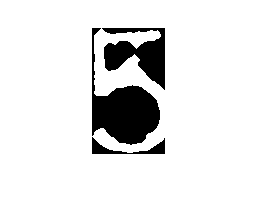

current_max = 1.0057e+08

digits2 =      1     0     0


current_max = 9.6258e+07

current_max = 1.0343e+08

digits2 =      3     0     0


current_max = 118212390

digits2 =      4     0     0


current_max = 1.0039e+08

current_max = 1.0486e+08

current_max = 1.0834e+08

current_max = 98131395

current_max = 9.6587e+07

current_max = 1.0404e+08

current_max = 117645270

current_max = 1.0258e+08

current_max = 1.0597e+08

current_max = 1.0651e+08

current_max = 9.7671e+07

current_max = 9.6921e+07

current_max = 105093660

current_max = 117894915

current_max = 101917380

current_max = 1.0510e+08

current_max = 106190415

current_max = 9.9232e+07

current_max = 9.7605e+07

current_max = 105909405

current_max = 1.1808e+08

current_max = 1.0065e+08

current_max = 105510585

current_max = 1.0800e+08

current_max = 1.1000e+08

current_max = 1.0066e+08

current_max = 124208970

digits2 =     31     0     0


current_max = 1.3288e+08

digits2 =     32     0     0


current_max = 118357740

current_max = 1.2388e+08

current_max = 111155010

current_max = 1.1098e+08

current_max = 1.0077e+08

current_max = 123930765

current_max = 1.3091e+08

current_max = 1.1655e+08

current_max = 1.2461e+08

current_max = 111706575

current_max = 1.1215e+08

current_max = 1.0057e+08

current_max = 1.2440e+08

current_max = 1.3222e+08

current_max = 1.1720e+08

current_max = 1.2432e+08

current_max = 1.1196e+08

current_max = 1.1205e+08

current_max = 1.0054e+08

current_max = 1.2439e+08

current_max = 131996925

current_max = 1.1805e+08

current_max = 1.2408e+08

current_max = 112501920

current_max = 88962105

current_max = 1.0014e+08

current_max = 115050135

current_max = 1.8825e+08

digits2 =     60     0     0


current_max = 1.2655e+08

current_max = 9.5385e+07

current_max = 9.4208e+07

current_max = 8.7844e+07

current_max = 1.0104e+08

current_max = 115202625

current_max = 187819995

current_max = 1.2506e+08

current_max = 9.7663e+07

current_max = 9.3654e+07

current_max = 8.7398e+07

current_max = 1.0078e+08

current_max = 1.1486e+08

current_max = 188102790

current_max = 126166095

current_max = 9.3754e+07

current_max = 9.3065e+07

current_max = 8.7840e+07

current_max = 100550835

current_max = 1.1615e+08

current_max = 1.8771e+08

current_max = 128019180

current_max = 9.6860e+07

current_max = 93351930

    %Find best template match
    digits = zeros(1,3);
    digits2 = zeros(1,3);
    for i=1:1
        croppedDigit = crop_edges(digitThirds(:,:,i));
        figure();
        imshow(croppedDigit);
        greyDigit = croppedDigit*255;
        max_value=0;
        current_max=0;
        for l = 1:nfiles
            correlation_map = templatematch(greyDigit,templates{1,l});
            current_max = max(correlation_map,[],'all')
            if(current_max > max_value)
                max_value=current_max;
                digits(i)=map_digit(nfiles,l);
                digits2(i)=l
            end
        end
    end

    S = digits;

I = im2double(im2gray(O));
%Filter structured noise in fourier domain
fourier = fftshift(fft2(I));
fourier(160,211) = 0;
fourier(157,204) = 0;
fourier(166,225) = 0;
fourier(169,232) = 0;
filteredImage = ifft2(ifftshift(fourier)) + mean2(I);
filteredImage = mat2gray(real(filteredImage));
blurred = imgaussfilt(filteredImage,2.5)

blurred =     0.7572    0.7541    0.7522    0.7529    0.7572    0.7650    0.7741    0.7810    0.7830    0.7791    0.7699    0.7561    0.7406    0.7279    0.7215    0.7222    0.7282    0.7364    0.7435    0.7462    0.7435    0.7370    0.7302    0.7249    0.7219    0.7208    0.7212    0.7229    0.7249    0.7252    0.7212    0.7104    0.6921    0.6684    0.6440    0.6228    0.6084    0.6021    0.6030    0.6101    0.6235    0.6436    0.6698    0.6991    0.7277    0.7520    0.7699    0.7806    0.7847    0.7846
    0.7630    0.7592    0.7560    0.7547    0.7567    0.7624    0.7701    0.7765    0.7787    0.7753    0.7659    0.7510    0.7333    0.7178    0.7087    0.7076    0.7131    0.7222    0.7310    0.7356    0.7342    0.7280    0.7205    0.7141    0.7105    0.7098    0.7119    0.7162    0.7215    0.7255    0.7256    0.7198    0.7072    0.6896    0.6707    0.6535    0.6408    0.6337    0.6318    0.6345    0.6421    0.6555    0.6741    0.6955    0.7165    0.7342    0.7473    0.7552    0.758

noisyDigits = blurred < 0.65;
% Remove gaussian noise using energy minimi
% sation
% Limit to 1000 as unnecessary to go further

disk = strel("disk",1);
binaryImage = imerode(noisyDigits,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imerode(binaryImage,disk);
binaryImage = imdilate(binaryImage,disk);
binaryImage = imdilate(binaryImage,disk);
